## Sensitive analysis

% load models
% old models
baseFolderOld='~/drive/bioenergeticsPD/results/modelGeneration/models';
% old with constrain
load([baseFolderOld filesep 'neuron/synaptic/SYN1.mat'])
SYN.SYN1=SYN1;
SYN.SYN1.genes = regexprep(SYN.SYN1.genes, '\.\d', '');
% old without constrain
load([baseFolderOld filesep 'neuron/synaptic/unconstrained/SYN1_UNCONSTRAINED.mat'])
SYN.SYN1Unconstrained=SYN1_UNCONSTRAINED;
SYN.SYN1Unconstrained.genes = regexprep(SYN.SYN1Unconstrained.genes, '\.\d', '');

% new models
param.tissueSpecificSolver='fastCore';
switch param.tissueSpecificSolver
    case 'fastCore'
        baseFolderNew='~/drive/bioenergeticsPD/fromXi/model/fastcore';
    case 'thermoKernel'
        baseFolderNew='~/drive/bioenergeticsPD/fromXi/model/thermokernel';
end

% SYN models

% new with constrain
load([baseFolderNew filesep 'synaptic_model/synaptic_model.mat'])
SYN.SYN2=GeneratedModel;
% new without constrain
load([baseFolderNew filesep 'synaptic_unconstrained_model/synaptic_unconstrained_model.mat'])
SYN.SYN2Unconstrained=GeneratedModel;

%
SYN=ChangeOldModels(SYN);

### In the model, when maximising ATP production (ATPM), what is the reduced cost of ATP synthesis? 

% for the reduced cost of ATPS4mi in new SYN model
modelOri1=SYN.SYN1;
modelOri1=changeObjective(modelOri1,'ATPM');
FBAsolution_maxATP1=optimizeCbModel(modelOri1,'max',1e-6);
rcost1 = FBAsolution_maxATP1.w;
rcost1(abs(rcost1)<1e-4)=0;
flux1=FBAsolution_maxATP1.v;
% printFluxVector(modelOri1, [modelOri1.lb,flux1,modelOri1.ub,rcost1], 1)
index=find(rcost1~=0);
corerxns=table(string(modelOri1.rxns(index)),modelOri1.lb(index),modelOri1.ub(index),flux1(index),rcost1(index));
corerxns.Properties.VariableNames={'rxnID','lb','ub','flux','rcost'}

corerxns = 298×5 table
       rxnID       lb     ub     flux      rcost   
    ___________    __    ____    ____    __________

    "2AMADPTm"     0     1000     0      0.00015299
    "2OXOADOXm"    0     1000     0      0.00039218
    "3HLYTCL"      0     1000     0      0.00083126
    "3SPYRSPm"     0     1000     0      0.00030053
    "42A12BOOX"    0     1000     0      0.00025697
    "AASAD3m"      0     1000     0      0.00022303
    "ACCOACm"      0     1000     0      0.00056463
    "ACGALK"       0     1000     0      0.00033138
    "ACGAM6PSi"    0     1000     0      0.00030657
    "ACGAMK"       0     1000     0      0.00033138
    "ACHEe"        0     1000     0      0.00013402
    "ACHVESSEC"    0     1000     0      0.00095738
    "ACP1_FMN_"    0     1000     0      0.00063694
    "ADNCYC"       0     1

%
ind=contains(modelOri1.rxns,'ATPS4mi');
{'ATPS4mi',modelOri1.lb(ind),modelOri1.ub(ind),flux1(ind),rcost1(ind)}

ans = 1×5 cell array
    {'ATPS4mi'}    {[0]}    {[1000]}    {[24.6159]}    {[0]}


model1=modelOri1;
model1 = changeRxnBounds(model1,'ATPS4mi',24,'b');%flux1(ind)
FBAsolution1=optimizeCbModel(model1,'max',1e-6);
ind=contains(model1.rxns,'ATPS4mi');
{'ATPS4mi',model1.lb(ind),model1.ub(ind),FBAsolution1.v(ind),FBAsolution1.w(ind)}

ans = 1×5 cell array
    {'ATPS4mi'}    {[24]}    {[24]}    {[24]}    {[-1.8786e-05]}


% find uptake rxns
[ex1,up1]=findExcRxns(modelOri1);
% find uptake from rxns with flux
k=flux1~=0;
UP_flux1=table(string(modelOri1.rxns(k & up1)),modelOri1.lb(k & up1),modelOri1.ub(k & up1),flux1(k & up1),rcost1(k & up1));
UP_flux1.Properties.VariableNames={'ExchangeRxns','lb','ub','flux','rcost'}

UP_flux1 = 103×5 table
      ExchangeRxns          lb           ub          flux          rcost   
    ________________    __________    ________    __________    ___________

    "EX_2hb[e]"              -1000        1000       -7.4559              0
    "EX_3aib[e]"        -0.0024426        1000        14.602              0
    "EX_acetone[e]"          -1000        1000        1.3316              0
    "EX_bhb[e]"           -0.16992    -0.01062      -0.01062    -0.00012719
    "EX_chsterol[e]"    -0.0052186           0    -0.0052186              0
    "EX_creat[e]"            -1000        1000       0.68117              0
    "EX_crn[e]"              -1000        1000       -32.813              0
    "EX_dag_hs[e]"           -1000        1000       -8.0601              0
    "EX_gthrd[e]"            -1000        1000

% find uptake from rxns with rcost
s=rcost1~=0;
UP1=table(string(modelOri1.rxns(s & up1)),modelOri1.lb(s & up1),modelOri1.ub(s & up1),flux1(s & up1),rcost1(s & up1));
UP1.Properties.VariableNames={'ExchangeRxns','lb','ub','flux','rcost'}

UP1 = 14×5 table
    ExchangeRxns        lb           ub         flux          rcost   
    _____________    _________    ________    _________    ___________

    "EX_bhb[e]"       -0.16992    -0.01062     -0.01062    -0.00012719
    "EX_4mop[e]"         -1000           0            0    -0.00076057
    "EX_oaa[e]"          -1000           0            0     -0.0001016
    "EX_acac[e]"      -0.12744    -0.01593     -0.01593    -0.00010438
    "EX_akg[e]"             -1           0            0    -0.00016289
    "EX_lac_L[e]"        -6.48     0.83898      0.83898    -0.00013544
    "EX_o2[e]"          -17.53     -3.0459       -17.53     0.00077558
    "EX_pro_L[e]"    -0.083898    0.070092     0.070092    -0.00017098
    "EX_val_L[e]"     -0.11682      0.0531     -0.11682      0.0012953
    "EX_gly[e]"      -0.056286 


model1=modelOri1;
model1 = changeRxnBounds(model1,'ATPM',1000,'u'); % relax ATPM?
FBAsolution1=optimizeCbModel(model1,'max',1e-6);
FBAsolution1.f;

% find the rcost of ATP production rxns
model=modelOri1;
ATPcontributingRxns

corerxns(ismember(corerxns.rxnID,RxnsNamesAll),:)  % no rcost for ATP production rxns

% for the reduced cost of ATPS4m in new SYN model
modelOri2=SYN.SYN2;
modelOri2=changeObjective(modelOri2,'ATPM');
FBAsolution_maxATP2=optimizeCbModel(modelOri2,'max',1e-6);
rcost2 = FBAsolution_maxATP2.w;
% rcost2(abs(rcost2)<1e-4)=0;
flux2=FBAsolution_maxATP2.v;
% printFluxVector(modelOri2, [modelOri2.lb,flux2,modelOri2.ub,rcost2], 1)
index=find(rcost2~=0);
corerxns=table(string(modelOri2.rxns(index)),modelOri2.lb(index),modelOri2.ub(index),flux2(index),rcost2(index));
corerxns.Properties.VariableNames={'rxnID','lb','ub','flux','rcost'}

corerxns = 360×5 table
       rxnID        lb     ub     flux      rcost   
    ____________    __    ____    ____    __________

    "34DHPLACOX"    0     1000     0      6.7895e-05
    "3SALACBOXL"    0     1000     0       0.0012805
    "42A12BOOX"     0     1000     0      0.00071018
    "AASAD3m"       0     1000     0      0.00028693
    "ABTti"         0     1000     0      4.4934e-05
    "ACACT1x"       0     1000     0      9.9728e-06
    "ACCOACm"       0     1000     0      0.00031447
    "ACGALK"        0     1000     0      0.00036762
    "ACGAMK"        0     1000     0      0.00028462
    "ACGAMtly"      0     1000     0      5.8197e-05
    "ACHEe"         0     1000     0      4.6259e-05
    "ACHVESSEC"     0     1000     0        0.001142
    "ACOAD1fm"      0     1000     0        7.84e-05
    "ACP1_F

% find uptake rxns
[ex2,up2]=findExcRxns(modelOri2);
% find uptake from rxns with flux
k=flux2~=0;
UP_flux2=table(string(modelOri2.rxns(k & up2)),modelOri2.lb(k & up2),modelOri2.ub(k & up2),flux2(k & up2),rcost2(k & up2));
UP_flux2.Properties.VariableNames={'ExchangeRxns','lb','ub','flux','rcost'}

UP_flux2 = 139×5 table
      ExchangeRxns          lb           ub          flux          rcost   
    ________________    __________    ________    __________    ___________

    "EX_2hb[e]"              -1000        1000        14.272              0
    "EX_3aib[e]"        -0.0024426        1000        21.398              0
    "EX_7thf[e]"             -1000        1000      -0.12719              0
    "EX_acetone[e]"          -1000        1000       0.02655              0
    "EX_ascb_L[e]"           -1000        1000       -5.6174              0
    "EX_bhb[e]"           -0.16992    -0.01062      -0.01062    -4.5817e-05
    "EX_chsterol[e]"    -0.0052186           0    -0.0052186     2.2969e-08
    "EX_chtn[e]"             -1000        1000       -25.366              0
    "EX_creat[e]"            -1000        1000

% find uptake from rxns with rcost
s=rcost2~=0;
UP2=table(string(modelOri2.rxns(s & up)),modelOri2.lb(s & up),modelOri2.ub(s & up),flux2(s & up),rcost2(s & up));
UP2.Properties.VariableNames={'ExchangeRxns','lb','ub','flux','rcost'} 

UP2 = 28×5 table
      ExchangeRxns          lb             ub           flux           rcost   
    ________________    ___________    __________    ___________    ___________

    "EX_bhb[e]"            -0.16992      -0.01062       -0.01062    -4.5817e-05
    "EX_chsterol[e]"     -0.0052186             0     -0.0052186     2.2969e-08
    "EX_pe_hs[e]"         -0.000531          1000      -0.000531     1.2458e-05
    "EX_ps_hs[e]"         -0.000531          1000      -0.000531     5.8367e-05
    "EX_oaa[e]"               -1000             0              0    -1.9531e-05
    "sink_C02528[c]"    -0.00032554    0.00032554    -0.00032554     2.1085e-05
    "sink_dchac[c]"         -0.0001        0.0001         0.0001    -7.4154e-06
    "EX_acac[e]"           -0.12744      -0.01593       -0.01593    -0.00010398
    "EX_akg[


%
ind=contains(modelOri2.rxns,'ATPS4mi');
{'ATPS4mi',modelOri2.lb(ind),modelOri2.ub(ind),flux2(ind),rcost2(ind)} % no influence for ATP synthesis rxns?

ans = 1×5 cell array
    {'ATPS4mi'}    {[0]}    {[1000]}    {[13.4632]}    {[0]}


model2=modelOri2;
model2 = changeRxnBounds(model2,'ATPS4mi',17,'b');%flux2(ind)
FBAsolution2=optimizeCbModel(model2,'max',1e-6);
ind=contains(model2.rxns,'ATPS4mi');
{'ATPS4mi',model2.lb(ind),model2.ub(ind),FBAsolution2.v(ind),FBAsolution2.w(ind)}

ans = 1×5 cell array
    {'ATPS4mi'}    {[17]}    {[17]}    {[17]}    {[3.6678e-05]}


model2=modelOri2;
model2 = changeRxnBounds(model2,'ATPM',1000,'u'); % relax ATPM?
FBAsolution2=optimizeCbModel(model2,'max',1e-6);
FBAsolution2.f

ans = 1000

% find the rcost of all ATP production rxns
model=modelOri2;
ATPcontributingRxns
corerxns(ismember(corerxns.rxnID,RxnsNamesAll),:)  % no rcost for ATP production rxns


ans =

  0×5 empty table



% compare flux of uptake rxns
uniqueUPflux1= UP_flux1(~ismember(UP_flux1.ExchangeRxns,UP_flux2.ExchangeRxns),:)

uniqueUPflux1 = 29×5 table
      ExchangeRxns        lb       ub        flux        rcost
    _________________    _____    ____    ___________    _____

    "EX_imp[e]"          -1000    1000         6.5448      0  
    "EX_inost[e]"        -1000    1000         -4.125      0  
    "EX_leuktrC4[e]"     -1000    1000        -39.791      0  
    "EX_prostgd2[e]"     -1000    1000         7.8563      0  
    "EX_prostgf2[e]"     -1000    1000        -7.8563      0  
    "EX_utp[e]"          -1000    1000        -127.78      0  
    "EX_HC02205[e]"      -1000    1000         7.6605      0  
    "EX_3mob[e]"         -1000    1000        0.11682      0  
    "EX_ahcys[e]"        -1000    1000        0.58818      0  
    "EX_cala[e]"         -1000    1000          61.72      0  
    "EX_ethamp[e]"       -1000    1000        

uniqueUPflux2= UP_flux2(~ismember(UP_flux2.ExchangeRxns,UP_flux1.ExchangeRxns),:)

uniqueUPflux2 = 65×5 table
      ExchangeRxns       lb       ub       flux      rcost
    ________________    _____    ____    ________    _____

    "EX_7thf[e]"        -1000    1000    -0.12719      0  
    "EX_ascb_L[e]"      -1000    1000     -5.6174      0  
    "EX_chtn[e]"        -1000    1000     -25.366      0  
    "EX_cyan[e]"        -1000    1000    -0.85413      0  
    "EX_i[e]"           -1000    1000     -12.536      0  
    "EX_leuktrD4[e]"    -1000    1000      0.3325      0  
    "EX_oagt3_hs[e]"    -1000    1000     0.60689      0  
    "EX_peplys[e]"      -1000    1000     -2.4545      0  
    "EX_retnglc[e]"     -1000    1000      9.3298      0  
    "EX_tcynt[e]"       -1000    1000     0.85413      0  
    "EX_thf[e]"         -1000    1000     0.12719      0  
    "EX_thyox_L[e]"     -1000    10

% compare rcost of uptake rxns
uniqueUP1= UP1(~ismember(UP1.ExchangeRxns,UP2.ExchangeRxns),:)

uniqueUP1 = 4×5 table
    ExchangeRxns        lb           ub         flux          rcost   
    _____________    _________    ________    _________    ___________

    "EX_4mop[e]"         -1000           0            0    -0.00076057
    "EX_pro_L[e]"    -0.083898    0.070092     0.070092    -0.00017098
    "EX_tyr_L[e]"    -0.043542           0    -0.043542     0.00013592
    "EX_trp_L[e]"    -0.087084           0            0    -0.00026697


uniqueUP2= UP2(~ismember(UP2.ExchangeRxns,UP1.ExchangeRxns),:)

uniqueUP2 = 18×5 table
      ExchangeRxns          lb             ub           flux           rcost   
    ________________    ___________    __________    ___________    ___________

    "EX_chsterol[e]"     -0.0052186             0     -0.0052186     2.2969e-08
    "EX_pe_hs[e]"         -0.000531          1000      -0.000531     1.2458e-05
    "EX_ps_hs[e]"         -0.000531          1000      -0.000531     5.8367e-05
    "sink_C02528[c]"    -0.00032554    0.00032554    -0.00032554     2.1085e-05
    "sink_dchac[c]"         -0.0001        0.0001         0.0001    -7.4154e-06
    "EX_asn_L[e]"         -0.009558      0.039294      -0.009558     7.8983e-05
    "EX_glu_L[e]"         -0.046728      0.049914      -0.046728     4.3166e-05
    "EX_ile_L[e]"         -0.043542      0.004248      -0.043542     4.7644e-05
    "E

shadow price?

when maximising ATPM, which [e] mets with the highest shadow prices (exchange rxns)?

% identify ex mets in model1
exmetsInd=contains(string(modelOri1.mets), '[e]');
exmets=modelOri1.mets(exmetsInd);
ShadowEx1=table(exmets,modelOri1.metNames(exmetsInd),FBAsolution_maxATP1.y(exmetsInd));
ShadowEx1.Properties.VariableNames{2}='metNames';
ShadowEx1.Properties.VariableNames{3}='ShadowPrice';
ShadowEx1.absShadow=abs(ShadowEx1.ShadowPrice);
% ShadowEx1=ShadowEx1(abs(ShadowEx1.ShadowPrice)>1e-4,:);
ShadowEx1=sortrows(ShadowEx1,"absShadow","descend")

ShadowEx1 = 253×4 table
        exmets                         metNames                     ShadowPrice    absShadow 
    _______________    _________________________________________    ___________    __________

    {'biliverd[e]'}    {'Biliverdin'                           }      0.0020671     0.0020671
    {'HC01361[e]' }    {'Dihydroneopterin'                     }      0.0017663     0.0017663
    {'o2s[e]'     }    {'Superoxide'                           }      0.0014506     0.0014506
    {'val_L[e]'   }    {'L-Valine'                             }      0.0012954     0.0012954
    {'nwharg[e]'  }    {'N-(Omega)-Hydroxyarginine'            }      0.0011976     0.0011976
    {'h2o2[e]'    }    {'Hydrogen Peroxide'                    }      0.0008948     0.0008948
    {'o2[e]'      }    {'Oxygen'                               }     0.00079311    0.00

% identify ex mets in model2
exmetsInd=contains(string(modelOri2.mets), '[e]');
exmets=modelOri2.mets(exmetsInd);
ShadowEx2=table(exmets,modelOri2.metNames(exmetsInd),FBAsolution_maxATP2.y(exmetsInd));
ShadowEx2.Properties.VariableNames{2}='metNames';
ShadowEx2.Properties.VariableNames{3}='ShadowPrice';
ShadowEx2.absShadow=abs(ShadowEx2.ShadowPrice);
% ShadowEx1=ShadowEx1(abs(ShadowEx1.ShadowPrice)>1e-4,:);
ShadowEx2=sortrows(ShadowEx2,"absShadow","descend")

ShadowEx2 = 284×4 table
        exmets                    metNames                ShadowPrice    absShadow 
    _______________    _______________________________    ___________    __________

    {'o2[e]'      }    {'Oxygen'                     }      0.0011021     0.0011021
    {'atp[e]'     }    {'Adenosine Triphosphate'     }      0.0010642     0.0010642
    {'xol24oh[e]' }    {'(24S)-24-Hydroxycholesterol'}     -0.0010454     0.0010454
    {'o2s[e]'     }    {'Superoxide'                 }      0.0010355     0.0010355
    {'pan4p[e]'   }    {'Pantetheine 4-Phosphate'    }    -0.00098838    0.00098838
    {'h2o2[e]'    }    {'Hydrogen Peroxide'          }       0.000693      0.000693
    {'pglyc_hs[e]'}    {'Phosphatidylglycerol'       }     0.00065869    0.00065869
    {'akg[e]'     }    {'2-Oxoglutarate'             }    -0.00040558    0.00040558

Shadow price difference for model1 and model2

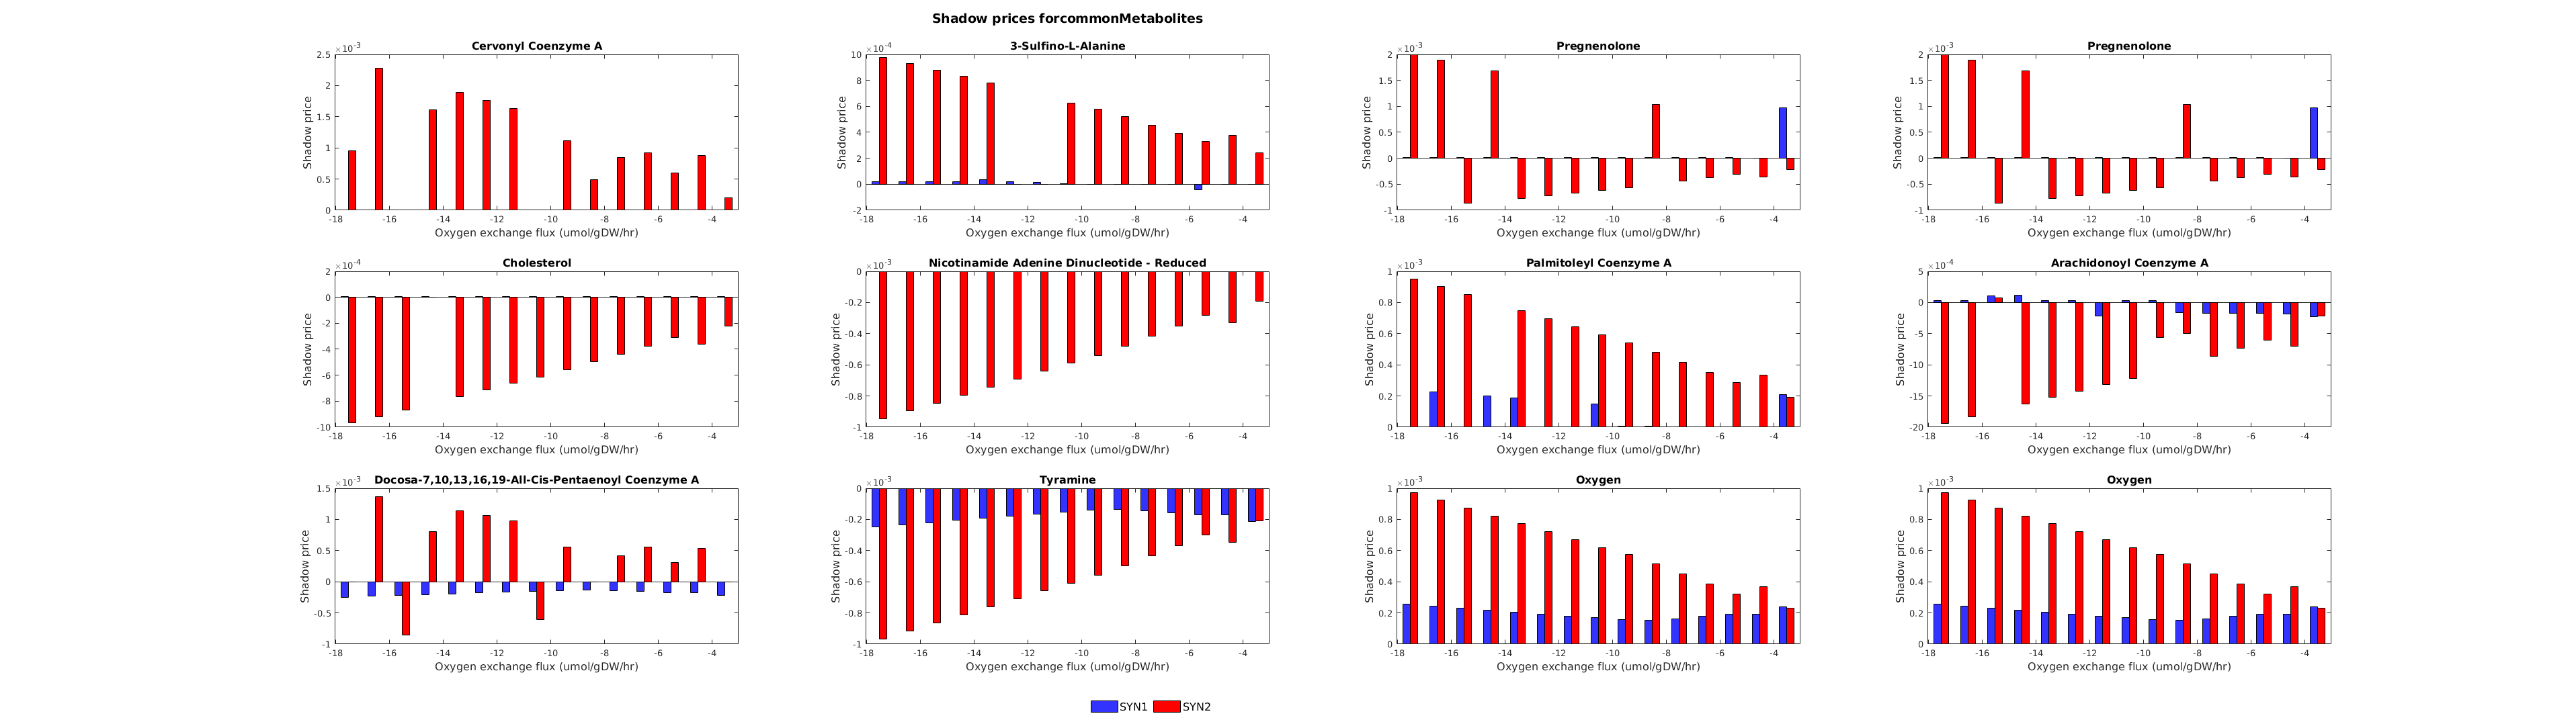

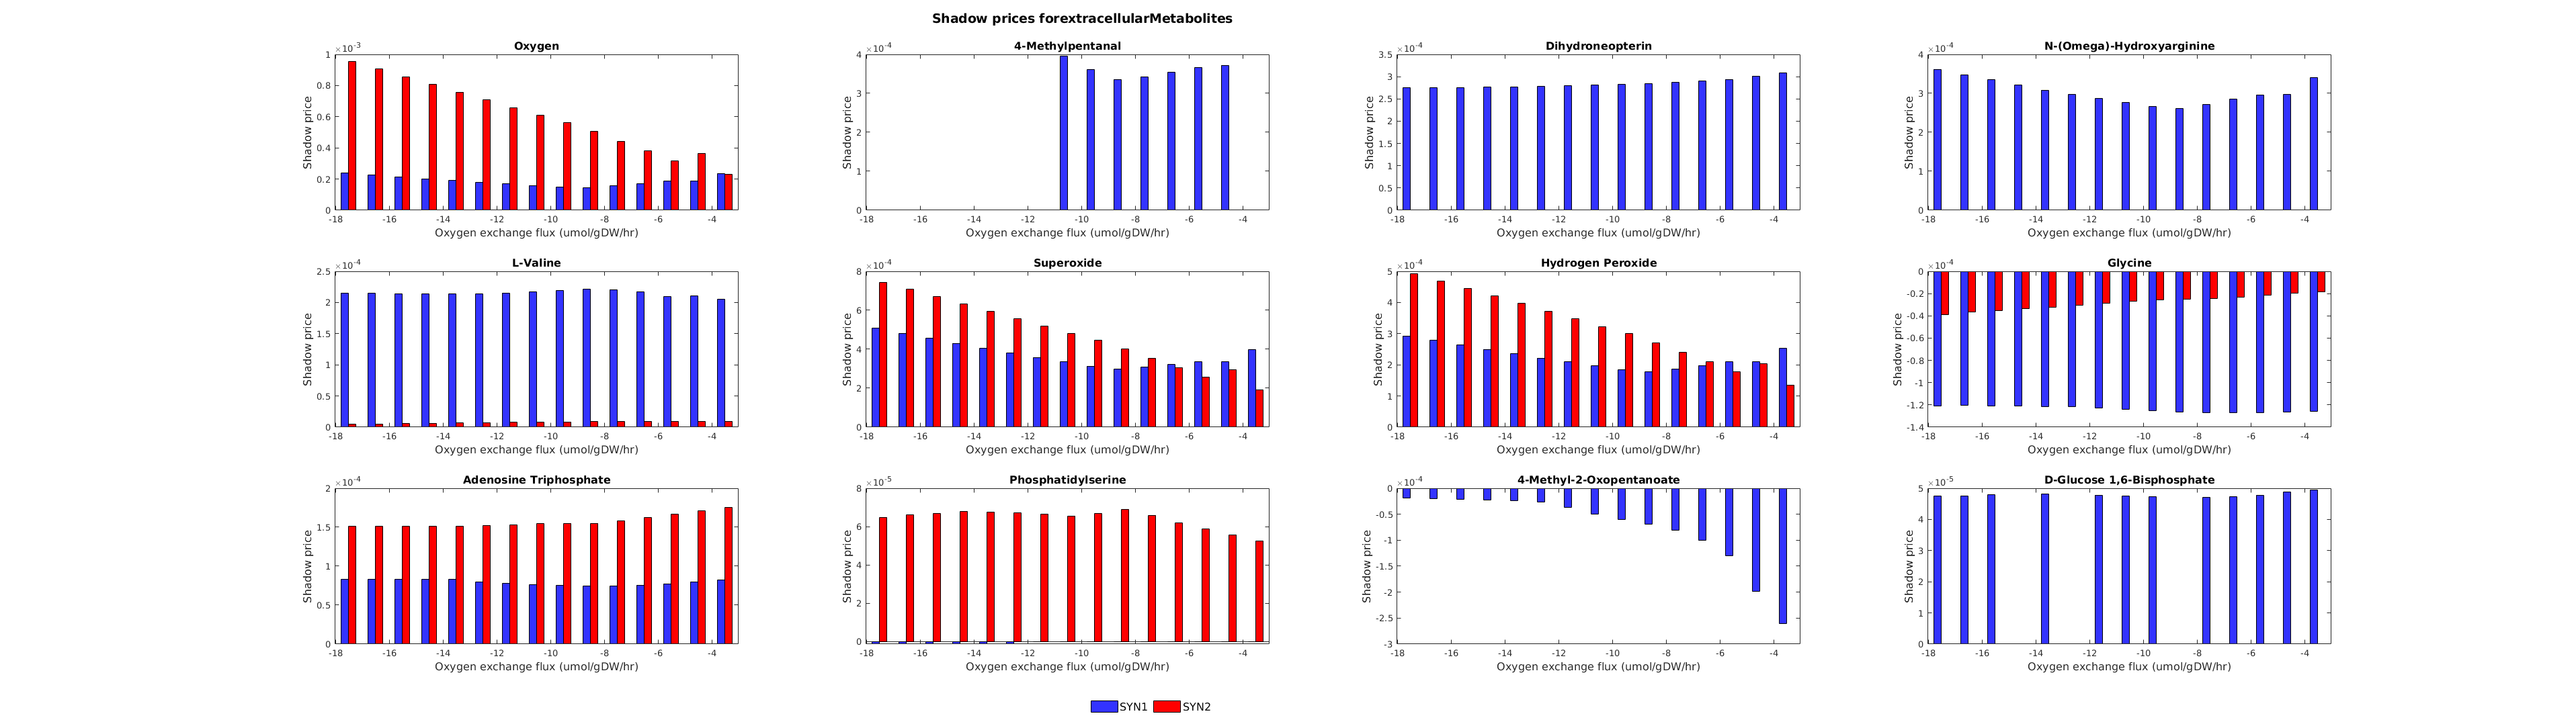

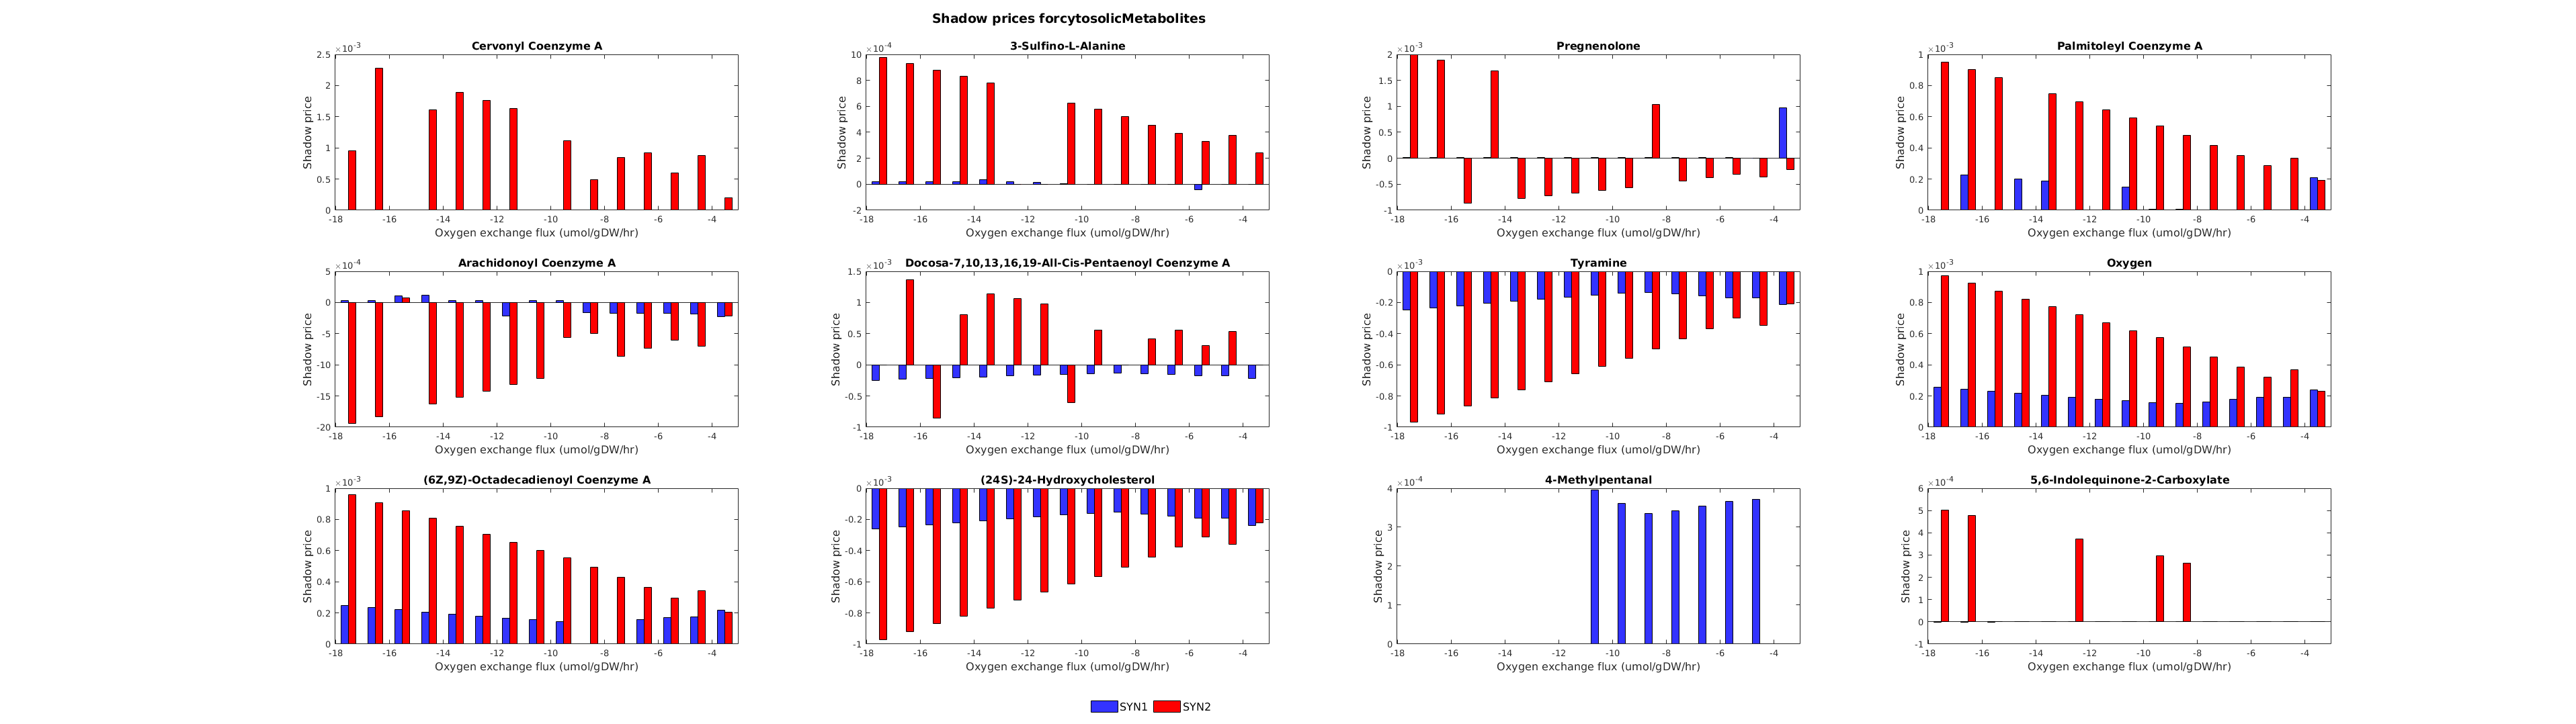

% ATPS4m vs OCR(oxygen exchange flux)
% objectiveFunction='ATPS4m'
labels={'SYN1','SYNPD1'};
plotShadowPrice(modelOri1,modelOri2,labels)